# F-16A Level 2 Sizing Analysis — Class-Based Example

This live script performs a Fidelity Level 2 sizing pass for the F-16A example using the toolkit classes supplied with the project. This version captures the W_TO value returned by SizingClassLevel2.size_aircraft().

Main objects used: * AircraftDesign * GeometryLevel2 * AeroLevel2 * PropulsionLevel2 * WeightLevel2 * MissionAnalysisLevel2 * ConstraintAnalysisClass * Requirements * SizingClassLevel2

The script assumes the corresponding class files, import utilities, design workbook, requirements table, constraints table, and mission profile are on the MATLAB path.

% clear; clc; close all;

## Project setup

Set this to the folder containing your classes, import utilities, design spreadsheet/workbook, requirements file, constraints file, and mission data.

projectRoot = pwd;
addpath(projectRoot);

% Change these names only if your local files use different names.
designName       = "F-16A Block 50";
requirementsName = "Requirements";
constraintsName  = "Constraints";
missionName      = "CAP";

% Basic class availability check. This catches path/name issues before the
% design object tries to import data.
requiredClasses = [ ...
    "AircraftDesign", ...
    "GeometryLevel2", ...
    "AeroLevel2", ...
    "PropulsionLevel2", ...
    "WeightLevel2", ...
    "MissionAnalysisLevel2", ...
    "ConstraintAnalysisClass", ...
    "Requirements", ...
    "SizingClassLevel2"];

for k = 1:numel(requiredClasses)
    assertClassOrFileExists(requiredClasses(k));
end

## Create the aircraft design object

AircraftDesign is the project-level object. It imports the design geometry, fuselage data, propulsion data, weight data, general aircraft data, and requirements reference.

design = AircraftDesign( ...
    designName, ...
    RequirementsName = requirementsName, ...
    ConstraintsName  = constraintsName, ...
    AutoLoad         = true);


% Keep the constraints filename explicit in case the design constructor was
% given a blank or nonstandard value.
if strlength(string(design.constraints_filename)) == 0
    design.constraints_filename = constraintsName;
end

disp("AircraftDesign object created:")

AircraftDesign object created:


disp(design)

  AircraftDesign with properties:

                     Name: "F-16A Block 50"
                     geom: [1×1 struct]
                  general: [1×1 struct]
               propulsion: [1×1 struct]
          propulsion_type: "low bpr turbofan"
                  weights: [1×1 struct]
                     type: "Jet fighter"
             requirements: [1×1 struct]
    requirements_filename: []
     constraints_filename: "Constraints"
            WeightResults: []
              AeroResults: []
        PropulsionResults: []
           internalvolume: []


## Build the Level 2 analysis objects

Level 2 uses more design geometry than Level 1. GeometryLevel2 computes component wetted areas from exposed planform/body estimates, AeroLevel2 uses equivalent skin-friction and wetted-area buildup for CD0, PropulsionLevel2 estimates installed TSFC from Mach/altitude/engine type, and WeightLevel2 uses a more parameterized empty-weight regression.

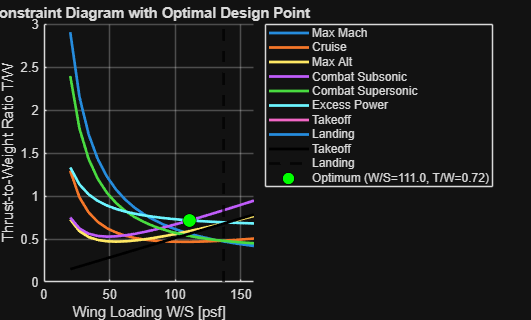

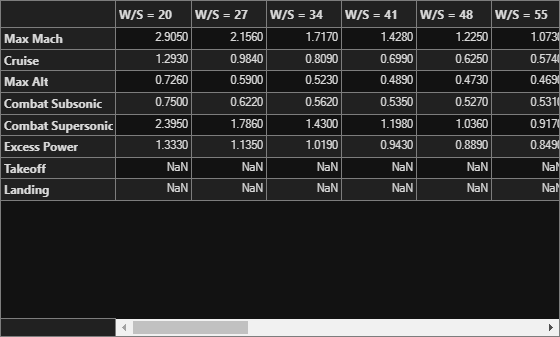

geometry_obj     = GeometryLevel2(design);
aero_obj         = AeroLevel2();
propulsion_obj   = PropulsionLevel2(design);
weight_obj       = WeightLevel2(design);
mission_obj      = MissionAnalysisLevel2(missionName);
constraint_obj   = ConstraintAnalysisClass(design);

requirements_obj = Requirements(design);
sizing_obj       = SizingClassLevel2();

% ConstraintAnalysisClass may either populate its properties directly or, if
% it behaves as a value class in your local inheritance tree, return the values
% through constraint_analysis(). This helper supports both behaviors.
[constraint_obj, constraintResults] = ensureConstraintResults(constraint_obj);

disp("Constraint-analysis summary:")

Constraint-analysis summary:


disp(constraintResults)

    OptimalWingLoading_psf    MinimumThrustLoading    LandingWingLoadingLimit_psf
    ______________________    ____________________    ___________________________
             111                    0.71662                     136.86           


## Configure Level 2 aerodynamic scalars

AeroLevel2 expects an equivalent skin-friction coefficient and Oswald span efficiency value. If these are not directly supplied by the design object, this example infers them from the cruise mission/constraint data where possible.

initialSref = weight_obj.W_TO_guess / constraint_obj.optimal_WS;
initialSwet = geometry_obj.get_design_S_wet(weight_obj.W_TO_guess);
[estimatedCf, estimatedE] = inferLevel2AeroInputs(mission_obj, constraint_obj, initialSref, initialSwet);

aero_obj.Cf = estimatedCf;
aero_obj.e_osw = estimatedE;

aeroInputSummary = table( ...
    estimatedCf, ...
    estimatedE, ...
    initialSref, ...
    initialSwet, ...
    'VariableNames', { ...
    'EquivalentSkinFriction_Cf', ...
    'OswaldEfficiency_e', ...
    'InitialWingReferenceArea_ft2', ...
    'InitialWettedArea_ft2'});

disp("Level 2 aerodynamic scalar inputs:")

Level 2 aerodynamic scalar inputs:


disp(aeroInputSummary)

    EquivalentSkinFriction_Cf    OswaldEfficiency_e    InitialWingReferenceArea_ft2    InitialWettedArea_ft2
    _________________________    __________________    ____________________________    _____________________
            0.0047364                  0.914                      405.41                       2311         


## Check Level 2 inputs used by the sizing loop

These are the key scalar inputs that drive the Level 2 sizing closure.

inputSummary = table( ...
    string(design.type), ...
    string(design.propulsion_type), ...
    weight_obj.W_TO_guess, ...
    weight_obj.W_fixed, ...
    constraint_obj.optimal_WS, ...
    constraint_obj.min_TW, ...
    requirements_obj.requirements.MaxMach.Mach, ...
    propulsion_obj.t_sl_dry, ...
    propulsion_obj.t_sl_wet, ...
    'VariableNames', { ...
    'AircraftType', ...
    'PropulsionType', ...
    'InitialWTOGuess_lbf', ...
    'FixedWeight_lbf', ...
    'OptimalWingLoading_psf', ...
    'RequiredThrustLoading', ...
    'MaxMach', ...
    'DrySeaLevelThrust_lbf', ...
    'WetSeaLevelThrust_lbf'});

disp(inputSummary)

    AircraftType       PropulsionType      InitialWTOGuess_lbf    FixedWeight_lbf    OptimalWingLoading_psf    RequiredThrustLoading    MaxMach    DrySeaLevelThrust_lbf    WetSeaLevelThrust_lbf
    _____________    __________________    ___________________    _______________    ______________________    _____________________    _______    _____________________    _____________________
    "Jet fighter"    "low bpr turbofan"           45000                5100                   111                     0.71662             1.6              15000                    23770        



missionSummary = summarizeMissionData(mission_obj.missiondata);
disp("Mission-profile summary extracted from mission_obj.missiondata:")

Mission-profile summary extracted from mission_obj.missiondata:


disp(missionSummary)

     Segment      MachNumber    Altitude_ft     Range_ft     Time_min    PayloadDrop_lbf     CD0       e       TSFC  
    __________    __________    ___________    __________    ________    _______________    _____    _____    _______
    "Startup"           0              0              NaN      NaN               0          0.027    0.914      1e-05
    "Taxi"              0              0              NaN      NaN               0          0.027    0.914      5e-05
    "Takeoff"        0.87              0              NaN      NaN               0          0.027    0.914     0.0001
    "Climb"          0.87          40000              NaN      NaN               0          0.027    0.9

## Run the project sizing class

This calls your SizingClassLevel2 method directly and captures the returned takeoff gross weight. The sizing class still displays its internal iteration table. A persistent trace is reconstructed in the next section for plots and reporting because the table is stored inside the value-class object.

W_TO_fromSizingClass = sizing_obj.size_aircraft( ...
    design, ...
    geometry_obj, ...
    mission_obj, ...
    weight_obj, ...
    propulsion_obj, ...
    constraint_obj, ...
    requirements_obj, ...
    aero_obj);

     WTO     W_fixed    Fuel_fraction    Empty_weight_fraction    Empty_weight    WTO_new    Difference    Percent_Diff
    _____    _______    _____________    _____________________    ____________    _______    __________    ____________
    45000     5100         0.23516              0.56961              25632         40716       -4284.4         -9.5209 
    40716     5100         0.23367              0.57554              23433         37509       -3206.5         -7.8754 
    37509     5100         0.23236              0.58044              21772         35094         -2415         -6.4383 
    35094     5100         0.23122              0.58445              20511         33266       -1828.1         -5.2092 
    3326


fprintf("\nSizingClassLevel2 returned W_TO = %.3f lbf.\n", W_TO_fromSizingClass);


SizingClassLevel2 returned W_TO = 27316.104 lbf.


fprintf("Reconstructing persistent trace for plots and saved results.\n");

Reconstructing persistent trace for plots and saved results.


## Reconstruct a persistent iteration trace using the same Level 2 objects

This loop mirrors the logic in SizingClassLevel2, but returns the iteration table to the live script for plots and inspection.

It does not create a separate F-16 object. The design data still comes from AircraftDesign and the calculations are still performed through the Level 2 objects supplied above.

[results_table, finalState, segmentTable] = runLevel2SizingTrace( ...
    design, ...
    geometry_obj, ...
    mission_obj, ...
    weight_obj, ...
    propulsion_obj, ...
    constraint_obj, ...
    requirements_obj, ...
    aero_obj);

disp("Persistent Level 2 sizing iteration table:")

Persistent Level 2 sizing iteration table:


disp(results_table)

    Iteration    WTO_lbf    FixedWeight_lbf    FuelUsed_lbf    FuelFraction    EmptyWeightFraction    OEW_lbf    WingReferenceArea_ft2    WettedArea_ft2       Cf        e_osw    CD0_est       K       LD_cruise    SeaLevelStaticThrust_lbf    CruiseTSFC_per_hr    DashTSFC_per_hr    LoiterTSFC_per_hr    WTO_new_lbf    Difference_lbf    PercentDifference
    _________    _______    _______________    ____________    ____________    ___________________    _______    _____________________    ________

## Final sizing summary

finalSummary = table( ...
    W_TO_fromSizingClass, ...
    finalState.W_TO_lbf, ...
    finalState.W_empty_lbf, ...
    finalState.W_fixed_lbf, ...
    finalState.W_fuel_lbf, ...
    finalState.fuel_fraction, ...
    finalState.empty_weight_fraction, ...
    finalState.S_ref_ft2, ...
    finalState.S_wet_ft2, ...
    finalState.CD0_est, ...
    finalState.K, ...
    finalState.LD_cruise, ...
    finalState.T0_lbf, ...
    finalState.TSFC_cruise_per_hr, ...
    finalState.TSFC_dash_per_hr, ...
    finalState.TSFC_loiter_per_hr, ...
    'VariableNames', { ...
    'SizingClassReturnedWTO_lbf', ...
    'TraceFinalWTO_lbf', ...
    'OEW_lbf', ...
    'FixedWeight_lbf', ...
    'FuelUsed_lbf', ...
    'FuelFraction', ...
    'EmptyWeightFraction', ...
    'WingReferenceArea_ft2', ...
    'WettedArea_ft2', ...
    'EstimatedCD0', ...
    'InducedDragFactor_K', ...
    'CruiseLiftToDrag', ...
    'SeaLevelStaticThrust_lbf', ...
    'CruiseTSFC_per_hr', ...
    'DashTSFC_per_hr', ...
    'LoiterTSFC_per_hr'});

disp("Final Level 2 sizing summary:")

Final Level 2 sizing summary:


disp(finalSummary)

    SizingClassReturnedWTO_lbf    TraceFinalWTO_lbf    OEW_lbf    FixedWeight_lbf    FuelUsed_lbf    FuelFraction    EmptyWeightFraction    WingReferenceArea_ft2    WettedArea_ft2    EstimatedCD0    InducedDragFactor_K    CruiseLiftToDrag    SeaLevelStaticThrust_lbf    CruiseTSFC_per_hr    DashTSFC_per_hr    LoiterTSFC_per_hr
    __________________________    _________________    _______    _______________    ____________    ____________    ___________________    _____________________    ______________    ____________    ___________________


WTO_return_difference = W_TO_fromSizingClass - finalState.W_TO_lbf;
fprintf("\nDifference between returned W_TO and trace final W_TO: %.6f lbf.\n", WTO_return_difference);


Difference between returned W_TO and trace final W_TO: 0.000000 lbf.



disp("Final mission-segment fuel table:")

Final mission-segment fuel table:


disp(segmentTable)

     Segment      W_in_lbf    W_out_lbf    FuelUsed_lbf
    __________    ________    _________    ____________
    "Takeoff"      27316        25950         1365.8   
    "Climb"        25950        25385         565.07   
    "Cruise"       25385        24655         729.91   
    "Dash"         24655        24056         599.47   
    "Combat"       24056        19481         174.97   
    "Cruise_1"     19481        18757         723.63   
    "Loiter"       18757        18214         543.59   
    "Landing"      18214        18123         91.069   


## Plot gross-weight convergence

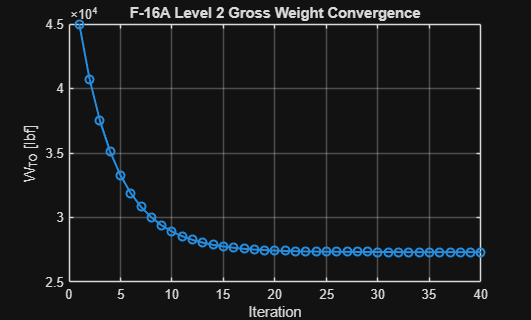

figure('Name', 'Level 2 Gross Weight Convergence');
plot(results_table.Iteration, results_table.WTO_lbf, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('W_{TO} [lbf]');
title('F-16A Level 2 Gross Weight Convergence');

## Plot closure error

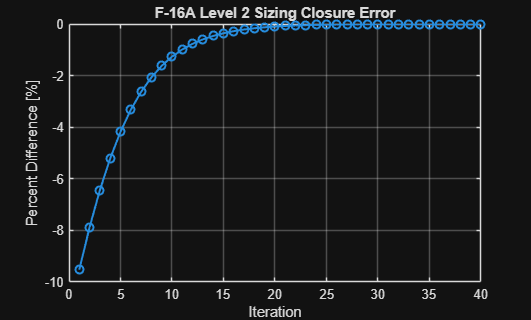

figure('Name', 'Level 2 Closure Error');
plot(results_table.Iteration, results_table.PercentDifference, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('Percent Difference [%]');
title('F-16A Level 2 Sizing Closure Error');

## Plot final weight breakdown

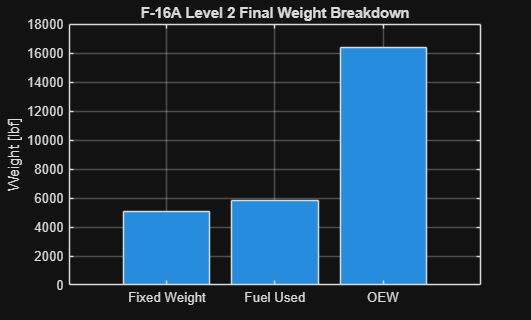

weightBreakdown = table( ...
    categorical(["OEW"; "Fuel Used"; "Fixed Weight"]), ...
    [finalState.W_empty_lbf; finalState.W_fuel_lbf; finalState.W_fixed_lbf], ...
    'VariableNames', {'Component', 'Weight_lbf'});

figure('Name', 'Level 2 Final Weight Breakdown');
bar(weightBreakdown.Component, weightBreakdown.Weight_lbf);
grid on;
ylabel('Weight [lbf]');
title('F-16A Level 2 Final Weight Breakdown');

## Plot final mission fuel by segment

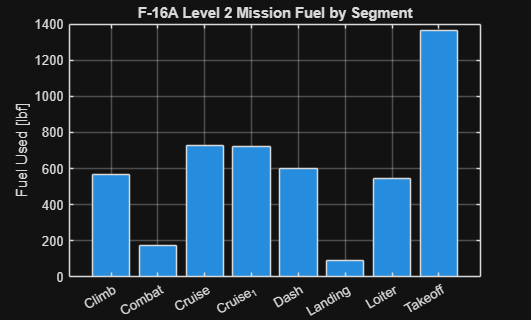

figure('Name', 'Level 2 Mission Fuel by Segment');
bar(categorical(segmentTable.Segment), segmentTable.FuelUsed_lbf);
grid on;
ylabel('Fuel Used [lbf]');
title('F-16A Level 2 Mission Fuel by Segment');

## Plot Level 2 aerodynamic snapshot

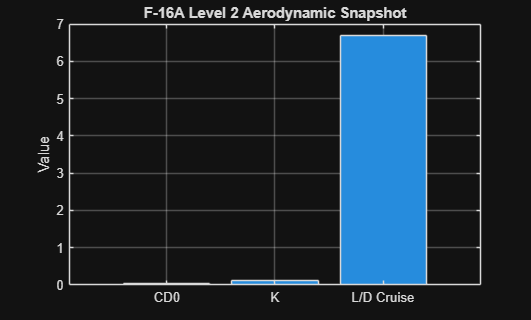

aeroSnapshot = table( ...
    categorical(["CD0"; "K"; "L/D Cruise"]), ...
    [finalState.CD0_est; finalState.K; finalState.LD_cruise], ...
    'VariableNames', {'Metric', 'Value'});

figure('Name', 'Level 2 Aerodynamic Snapshot');
bar(aeroSnapshot.Metric, aeroSnapshot.Value);
grid on;
ylabel('Value');
title('F-16A Level 2 Aerodynamic Snapshot');

## Save results into the AircraftDesign object

AircraftDesign is a handle class, so these assignments persist on the design object during this MATLAB session.

design.WeightResults.Level2SizingTable = results_table;
design.WeightResults.Level2Summary     = finalSummary;
design.WeightResults.Level2MissionFuel = segmentTable;
design.WeightResults.W_TO_fromSizingClass = W_TO_fromSizingClass;
design.WeightResults.W_TO              = finalState.W_TO_lbf;
design.WeightResults.OEW               = finalState.W_empty_lbf;
design.WeightResults.FuelUsed          = finalState.W_fuel_lbf;

design.AeroResults.Level2.Cf           = finalState.Cf;
design.AeroResults.Level2.e_osw        = finalState.e_osw;
design.AeroResults.Level2.CD0          = finalState.CD0_est;
design.AeroResults.Level2.K            = finalState.K;
design.AeroResults.Level2.LD_cruise    = finalState.LD_cruise;
design.AeroResults.Level2.S_wet        = finalState.S_wet_ft2;

design.PropulsionResults.Level2.T0     = finalState.T0_lbf;
design.PropulsionResults.Level2.TSFC_cruise_per_hr = finalState.TSFC_cruise_per_hr;
design.PropulsionResults.Level2.TSFC_dash_per_hr   = finalState.TSFC_dash_per_hr;
design.PropulsionResults.Level2.TSFC_loiter_per_hr = finalState.TSFC_loiter_per_hr;

fprintf("\nSaved Level 2 sizing results into design.WeightResults, design.AeroResults, and design.PropulsionResults.\n");


Saved Level 2 sizing results into design.WeightResults, design.AeroResults, and design.PropulsionResults.


## Local helper functions

function assertClassOrFileExists(className)
    className = string(className);
    existsAsClass = exist(char(className), 'class') == 8;
    existsAsFile  = exist(char(className + ".m"), 'file') == 2;

    if ~(existsAsClass || existsAsFile)
        error("Required class/file '%s' was not found on the MATLAB path. Check projectRoot/addpath.", className);
    end
end

function [constraint_obj, constraintResults] = ensureConstraintResults(constraint_obj)
    needsRun = isempty(constraint_obj.optimal_WS) || isempty(constraint_obj.min_TW);

    if needsRun
        [TW_table, T_Wto_takeoff, optimal_WS, min_TW, Landing, Wto_S_landing, T0_W0, W0_S_ref, T_Wto_required] = ...
            constraint_obj.constraint_analysis();

        constraint_obj.TW_table        = TW_table;
        constraint_obj.T_Wto_takeoff   = T_Wto_takeoff;
        constraint_obj.optimal_WS      = optimal_WS;
        constraint_obj.min_TW          = min_TW;
        constraint_obj.Landing         = Landing;
        constraint_obj.Wto_S_landing   = Wto_S_landing;
        constraint_obj.T0_W0           = T0_W0;
        constraint_obj.W0_S_ref        = W0_S_ref;
        constraint_obj.T_Wto_required  = T_Wto_required;
    end

    constraintResults = table( ...
        constraint_obj.optimal_WS, ...
        constraint_obj.min_TW, ...
        constraint_obj.Wto_S_landing, ...
        'VariableNames', {'OptimalWingLoading_psf', 'MinimumThrustLoading', 'LandingWingLoadingLimit_psf'});
end

function missionSummary = summarizeMissionData(missiondata)
    segmentNames = fieldnames(missiondata);
    rows = strings(0, 1);
    mach = nan(0, 1);
    altitude = nan(0, 1);
    range = nan(0, 1);
    time = nan(0, 1);
    payloadDrop = nan(0, 1);
    cd0 = nan(0, 1);
    e = nan(0, 1);
    tsfc = nan(0, 1);

    for i = 1:numel(segmentNames)
        name = segmentNames{i};
        segment = missiondata.(name);

        rows(end+1, 1) = string(name);
        mach(end+1, 1) = getFieldOrNaN(segment, 'MachNumber');
        altitude(end+1, 1) = getFieldOrNaN(segment, 'Altitudeft');
        range(end+1, 1) = getFieldOrNaN(segment, 'Rangeft');
        time(end+1, 1) = getFieldOrNaN(segment, 'Timemin');
        payloadDrop(end+1, 1) = getFieldOrNaN(segment, 'PayloadDroplbf');
        cd0(end+1, 1) = getFieldOrNaN(segment, 'CD0');
        e(end+1, 1) = getFieldOrNaN(segment, 'e');
        tsfc(end+1, 1) = getFieldOrNaN(segment, 'TSFC');
    end

    missionSummary = table(rows, mach, altitude, range, time, payloadDrop, cd0, e, tsfc, ...
        'VariableNames', {'Segment', 'MachNumber', 'Altitude_ft', 'Range_ft', 'Time_min', 'PayloadDrop_lbf', 'CD0', 'e', 'TSFC'});
end

function value = getFieldOrNaN(s, fieldName)
    if isstruct(s) && isfield(s, fieldName)
        value = s.(fieldName);
    elseif istable(s) && any(strcmp(s.Properties.VariableNames, fieldName))
        value = s.(fieldName);
    else
        value = NaN;
    end

    if ~isscalar(value) || ~isnumeric(value)
        value = NaN;
    end
end

function [Cf, e_osw] = inferLevel2AeroInputs(mission_obj, constraint_obj, S_ref, S_wet)
    cruiseCD0 = getMissionScalar(mission_obj.missiondata, 'Cruise', 'CD0');
    cruiseE   = getMissionScalar(mission_obj.missiondata, 'Cruise', 'e');

    if ~isfinite(cruiseCD0)
        cruiseCD0 = getConstraintScalar(constraint_obj, 'Cruise', 'CD0');
    end

    if ~isfinite(cruiseE)
        cruiseE = getConstraintScalar(constraint_obj, 'Cruise', 'e');
    end

    if isfinite(cruiseCD0) && isfinite(S_ref) && isfinite(S_wet) && S_wet > 0
        Cf = cruiseCD0 * S_ref / S_wet;
    else
        Cf = 0.0035;
        warning("Could not infer Cf from mission/constraint CD0. Using Cf = %.4f.", Cf);
    end

    if isfinite(cruiseE)
        e_osw = cruiseE;
    else
        e_osw = 0.75;
        warning("Could not infer Oswald efficiency from mission/constraint data. Using e = %.3f.", e_osw);
    end
end

function value = getMissionScalar(missiondata, segmentName, fieldName)
    value = NaN;
    if isfield(missiondata, segmentName)
        value = getFieldOrNaN(missiondata.(segmentName), fieldName);
    end
end

function value = getConstraintScalar(constraint_obj, rowName, varName)
    value = NaN;
    try
        if ~isempty(constraint_obj.constraints_table) && any(strcmp(constraint_obj.constraints_table.Row, rowName))
            row = constraint_obj.constraints_table(rowName, :);
            if any(strcmp(row.Properties.VariableNames, varName))
                value = row.(varName);
            end
        end
    catch
        value = NaN;
    end

    if ~isscalar(value) || ~isnumeric(value)
        value = NaN;
    end
end

function [results_table, finalState, segmentTable] = runLevel2SizingTrace(design, geometry_obj, mission_obj, weight_obj, propulsion_obj, constraint_obj, requirements_obj, aero_obj)
    W_S = constraint_obj.optimal_WS;
    T_W = constraint_obj.min_TW;

    assert(~isempty(W_S) && isfinite(W_S), 'constraint_obj.optimal_WS must be finite.');
    assert(~isempty(T_W) && isfinite(T_W), 'constraint_obj.min_TW must be finite.');

    W_TO = weight_obj.W_TO_guess;
    W_fixed = mission_obj.missiondata.Startup.PayloadFixedlbf;

    tol = 1e-3;
    maxIteration = 40;
    rows = [];
    lastSegmentTable = table();

    for iteration = 1:maxIteration
        geometry_obj.mainwings.S_ref = W_TO / W_S;
        geometry_obj.design.S_wet = geometry_obj.get_design_S_wet(W_TO);

        propulsion_obj.T0 = T_W * W_TO;

        weight_obj.W_TO = W_TO;
        weight_obj.W_fixed = W_fixed;

        % Keep AeroLevel2 scalars synchronized with the current geometry.
        [Cf_iter, e_iter] = inferLevel2AeroInputs(mission_obj, constraint_obj, geometry_obj.mainwings.S_ref, geometry_obj.design.S_wet);
        aero_obj.Cf = Cf_iter;
        aero_obj.e_osw = e_iter;

        [fuel_used, fuel_fraction] = mission_obj.get_mission_fuel( ...
            constraint_obj, ...
            design, ...
            geometry_obj, ...
            propulsion_obj, ...
            weight_obj);

        OEW = weight_obj.get_OEW( ...
            W_TO, ...
            W_TO, ...
            geometry_obj.mainwings.AR, ...
            propulsion_obj.T0, ...
            geometry_obj.mainwings.S_ref, ...
            requirements_obj.requirements.MaxMach.Mach, ...
            weight_obj.K_vs);

        OEW_frac = OEW / W_TO;

        W_TO_new = fuel_used + W_fixed + OEW;
        difference = W_TO_new - W_TO;
        percentDifference = 100 * difference / W_TO;

        [CD0_est, K, LD_cruise] = computeLevel2AeroSnapshot( ...
            aero_obj, ...
            geometry_obj, ...
            mission_obj, ...
            W_TO, ...
            Cf_iter, ...
            e_iter);

        [TSFC_cruise, TSFC_dash, TSFC_loiter] = computeLevel2TSFCSnapshot( ...
            propulsion_obj, ...
            design, ...
            mission_obj, ...
            W_TO);

        lastSegmentTable = estimateLevel2MissionSegments( ...
            mission_obj, ...
            propulsion_obj, ...
            design, ...
            W_TO, ...
            W_S, ...
            geometry_obj.mainwings.S_ref, ...
            geometry_obj.mainwings.AR);

        rows(end+1, :) = [ ...
            iteration, ...
            W_TO, ...
            W_fixed, ...
            fuel_used, ...
            fuel_fraction, ...
            OEW_frac, ...
            OEW, ...
            geometry_obj.mainwings.S_ref, ...
            geometry_obj.design.S_wet, ...
            Cf_iter, ...
            e_iter, ...
            CD0_est, ...
            K, ...
            LD_cruise, ...
            propulsion_obj.T0, ...
            TSFC_cruise * 3600, ...
            TSFC_dash * 3600, ...
            TSFC_loiter * 3600, ...
            W_TO_new, ...
            difference, ...
            percentDifference]; %#ok<AGROW>

        if abs(difference) < tol
            W_TO = W_TO_new;
            break;
        end

        W_TO = W_TO_new;
    end

    results_table = array2table(rows, 'VariableNames', { ...
        'Iteration', ...
        'WTO_lbf', ...
        'FixedWeight_lbf', ...
        'FuelUsed_lbf', ...
        'FuelFraction', ...
        'EmptyWeightFraction', ...
        'OEW_lbf', ...
        'WingReferenceArea_ft2', ...
        'WettedArea_ft2', ...
        'Cf', ...
        'e_osw', ...
        'CD0_est', ...
        'K', ...
        'LD_cruise', ...
        'SeaLevelStaticThrust_lbf', ...
        'CruiseTSFC_per_hr', ...
        'DashTSFC_per_hr', ...
        'LoiterTSFC_per_hr', ...
        'WTO_new_lbf', ...
        'Difference_lbf', ...
        'PercentDifference'});

    last = results_table(end, :);

    finalState = struct();
    finalState.W_TO_lbf = last.WTO_new_lbf;
    finalState.W_empty_lbf = last.OEW_lbf;
    finalState.W_fixed_lbf = last.FixedWeight_lbf;
    finalState.W_fuel_lbf = last.FuelUsed_lbf;
    finalState.fuel_fraction = last.FuelFraction;
    finalState.empty_weight_fraction = last.EmptyWeightFraction;
    finalState.S_ref_ft2 = last.WingReferenceArea_ft2;
    finalState.S_wet_ft2 = last.WettedArea_ft2;
    finalState.Cf = last.Cf;
    finalState.e_osw = last.e_osw;
    finalState.CD0_est = last.CD0_est;
    finalState.K = last.K;
    finalState.LD_cruise = last.LD_cruise;
    finalState.T0_lbf = last.SeaLevelStaticThrust_lbf;
    finalState.TSFC_cruise_per_hr = last.CruiseTSFC_per_hr;
    finalState.TSFC_dash_per_hr = last.DashTSFC_per_hr;
    finalState.TSFC_loiter_per_hr = last.LoiterTSFC_per_hr;

    segmentTable = lastSegmentTable;
end

function [CD0_est, K, LD_cruise] = computeLevel2AeroSnapshot(aero_obj, geometry_obj, mission_obj, W_TO, Cf, e_osw)
    S_ref = geometry_obj.mainwings.S_ref;
    S_wet = geometry_obj.design.S_wet;
    AR = geometry_obj.mainwings.AR;

    CD0_est = aero_obj.get_design_CD0(Cf, S_wet, S_ref);
    K = 1 / (pi * AR * e_osw);

    cruise = mission_obj.missiondata.Cruise;
    q = getFieldOrNaN(cruise, 'qlbfft2');

    if isfinite(q) && q > 0
        CL = 2 * W_TO / (q * S_ref);
        CD = CD0_est + K * CL^2;
        LD_cruise = CL / CD;
    else
        LD_cruise = NaN;
    end
end

function [TSFC_cruise, TSFC_dash, TSFC_loiter] = computeLevel2TSFCSnapshot(propulsion_obj, design, mission_obj, W_TO)
    cruise = mission_obj.missiondata.Cruise;
    dash = mission_obj.missiondata.Dash;
    loiter = mission_obj.missiondata.Loiter;

    TSFC_cruise = propulsion_obj.get_TSFC_installed( ...
        design.propulsion_type, ...
        [cruise.MachNumber, cruise.Altitudeft, 0, W_TO], ...
        "mil");

    TSFC_dash = propulsion_obj.get_TSFC_installed( ...
        design.propulsion_type, ...
        [dash.MachNumber, dash.Altitudeft, 0, W_TO], ...
        "max");

    TSFC_loiter = propulsion_obj.get_TSFC_installed( ...
        design.propulsion_type, ...
        [loiter.MachNumber, loiter.Altitudeft, 0, W_TO], ...
        "mil");
end

function segmentTable = estimateLevel2MissionSegments(mission_obj, propulsion_obj, design, W_TO, W_S, S_ref, AR)
    m = mission_obj.missiondata;

    segment = strings(0, 1);
    W_in = nan(0, 1);
    W_out = nan(0, 1);
    fuel = nan(0, 1);

    W_current = W_TO;

    [W_next, f] = takeoffSegment(W_current);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Takeoff", W_current, W_next, f);
    W_current = W_next;

    [W_next, f] = climbSegment(W_current, m.Climb.MachNumber);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Climb", W_current, W_next, f);
    W_current = W_next;

    TSFC_cruise = getMissionTSFCOrInstalled(m.Cruise, propulsion_obj, design, W_current, "mil");
    [W_next, f] = breguetRangeSegment(W_current, W_TO, W_S, TSFC_cruise, m.Cruise.Rangeft, m.Cruise.MachNumber*m.Cruise.afts, m.Cruise.qlbfft2, m.Cruise.CD0, m.Cruise.e, AR);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Cruise", W_current, W_next, f);
    W_current = W_next;

    TSFC_dash = getMissionTSFCOrInstalled(m.Dash, propulsion_obj, design, W_current, "max");
    [W_next, f] = breguetRangeSegment(W_current, W_TO, W_S, TSFC_dash, m.Dash.Rangeft, m.Dash.MachNumber*m.Dash.afts, m.Dash.qlbfft2, m.Dash.CD0, m.Dash.e, AR);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Dash", W_current, W_next, f);
    W_current = W_next;

    TSFC_combat = getMissionTSFCOrInstalled(m.Combat, propulsion_obj, design, W_current, "max");
    [W_next, f] = enduranceSegment(W_current, W_TO, W_S, TSFC_combat, m.Combat.Timemin, m.Combat.qlbfft2, m.Combat.CD0, m.Combat.e, AR, m.Combat.PayloadDroplbf);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Combat", W_current, W_next, f);
    W_current = W_next;

    TSFC_cruise2 = getMissionTSFCOrInstalled(m.Cruise_1, propulsion_obj, design, W_current, "max");
    [W_next, f] = breguetRangeSegment(W_current, W_TO, W_S, TSFC_cruise2, m.Cruise_1.Rangeft, m.Cruise_1.MachNumber*m.Cruise_1.afts, m.Cruise_1.qlbfft2, m.Cruise_1.CD0, m.Cruise_1.e, AR);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Cruise_1", W_current, W_next, f);
    W_current = W_next;

    TSFC_loiter = getMissionTSFCOrInstalled(m.Loiter, propulsion_obj, design, W_current, "mil");
    [W_next, f] = enduranceSegment(W_current, W_TO, W_S, TSFC_loiter, m.Loiter.Timemin, m.Loiter.qlbfft2, m.Loiter.CD0, m.Loiter.e, AR, 0);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Loiter", W_current, W_next, f);
    W_current = W_next;

    [W_next, f] = landingSegment(W_current);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Landing", W_current, W_next, f);

    segmentTable = table(segment, W_in, W_out, fuel, 'VariableNames', {'Segment', 'W_in_lbf', 'W_out_lbf', 'FuelUsed_lbf'});
end

function TSFC = getMissionTSFCOrInstalled(seg, propulsion_obj, design, W, powerSetting)
    TSFC = getFieldOrNaN(seg, 'TSFC');
    if ~isfinite(TSFC)
        TSFC = propulsion_obj.get_TSFC_installed( ...
            design.propulsion_type, ...
            [seg.MachNumber, seg.Altitudeft, 0, W], ...
            powerSetting);
    end
end

function LD = computeLDLevel2(W, W_TO, q, CD0, W_S, e, AR)
    W_by_WTO = W / W_TO;
    W_by_S = W_by_WTO * W_S;
    LD = 1 / ((q * CD0 / W_by_S) + (W_by_S / (q * pi * e * AR)));
end

function [W_out, fuel_used] = breguetRangeSegment(W_in, W_TO, W_S, TSFC, distance_ft, V_fts, q, CD0, e, AR)
    LD = computeLDLevel2(W_in, W_TO, q, CD0, W_S, e, AR);
    WF = exp(-((distance_ft * TSFC) / (V_fts * LD)));
    fuel_used = W_in * (1 - WF);
    W_out = W_in - fuel_used;
end

function [W_out, fuel_used] = enduranceSegment(W_in, W_TO, W_S, TSFC, time_min, q, CD0, e, AR, payloadDrop_lbf)
    LD = computeLDLevel2(W_in, W_TO, q, CD0, W_S, e, AR);
    WF = exp(-(time_min * 60 * TSFC / LD));
    fuel_used = W_in * (1 - WF);
    W_out = W_in - fuel_used - payloadDrop_lbf;
end

function [W_out, fuel_used] = climbSegment(W_in, Mach)
    WF = 1.0065 - 0.0325 * Mach;
    fuel_used = (1 - WF) * W_in;
    W_out = W_in - fuel_used;
end

function [W_out, fuel_used] = takeoffSegment(W_in)
    WF = 0.95;
    W_out = W_in * WF;
    fuel_used = W_in - W_out;
end

function [W_out, fuel_used] = landingSegment(W_in)
    WF = 0.995;
    W_out = W_in * WF;
    fuel_used = W_in - W_out;
end

function [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, name, win, wout, f)
    segment(end+1, 1) = string(name);
    W_in(end+1, 1) = win;
    W_out(end+1, 1) = wout;
    fuel(end+1, 1) = f;
end